# Grid analysis 2.0



% to obtain calcium wave properties

% - event freq (# of waves/min)
maxTime = 10.11614  % 1250 frames

maxTime = 10.1161

scale = 0.83027; %um/pixel
areaPG = (10*scale)^2 % area per grd

areaPG = 68.9348


con1 = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 1 movie 2 1x_ISCdata.mat')

con1 = struct with fields:
    ISCstruct: [1×1 struct]


con2 = load('20190815 exp270 mouse 4 tecta-cre cx26fl+ gcamp3 movie 2 prep 2 1x_ISCdata.mat')

con2 = struct with fields:
    ISCstruct: [1×1 struct]


con3 = load('20190822 exp274 tecta cx26fl+ gc3 mouse 1 prep 2 movie 2 1x_ISCdata.mat') % relatively poor ISCs

con3 = struct with fields:
    ISCstruct: [1×1 struct]


con4 = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 2 movie 2 1x_ISCdata.mat')

con4 = struct with fields:
    ISCstruct: [1×1 struct]


con5 = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 2 movie 1 1x_ISCdata.mat')

con5 = struct with fields:
    ISCstruct: [1×1 struct]


con6 = load('20191023 exp 292 mouse 7 prep 2 tecta cx26 fl+ gcamp3 1x movie 1_ISCdata.mat')

con6 = struct with fields:
    ISCstruct: [1×1 struct]


con7 = load('20191023 exp 292 mouse 4 prep 2 tecta cx26 fl+ gcamp3 1x movie 1_ISCdata.mat')

con7 = struct with fields:
    ISCstruct: [1×1 struct]


con8 = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 1 movie 1 1x_ISCdata.mat')

con8 = struct with fields:
    ISCstruct: [1×1 struct]



%events per 0.01 mm2
con1Freq = (length(con1.ISCstruct.event)/maxTime)/(size(con1.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con2Freq = (length(con2.ISCstruct.event)/maxTime)/(size(con2.ISCstruct.rois,2)*areaPG)*10000;
con3Freq = (length(con3.ISCstruct.event)/maxTime)/(size(con3.ISCstruct.rois,2)*areaPG)*10000;
con4Freq = (length(con4.ISCstruct.event)/maxTime)/(size(con4.ISCstruct.rois,2)*areaPG)*10000;
con5Freq = (length(con5.ISCstruct.event)/maxTime)/(size(con5.ISCstruct.rois,2)*areaPG)*10000;
con6Freq = (length(con6.ISCstruct.event)/maxTime)/(size(con6.ISCstruct.rois,2)*areaPG)*10000;
con7Freq = (length(con7.ISCstruct.event)/maxTime)/(size(con7.ISCstruct.rois,2)*areaPG)*10000;
con8Freq = (length(con8.ISCstruct.event)/maxTime)/(size(con8.ISCstruct.rois,2)*areaPG)*10000;

conFreq = [con1Freq,con2Freq,con3Freq,con4Freq,con5Freq,con6Freq,con7Freq,con8Freq]

conFreq =     2.6395    3.0189    2.9875    3.3894    3.2974    3.9886    4.6193    3.3894



cx261 = load('20190815 exp270 mouse 3 tecta-cre cx26flfl gcamp3 movie 2 prep 1 1x_ISCdata.mat')

cx261 = struct with fields:
    ISCstruct: [1×1 struct]


cx262 = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 1 movie 2 1x_ISCdata.mat')

cx262 = struct with fields:
    ISCstruct: [1×1 struct]


cx263 = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 2 movie 2 1x_ISCdata.mat')

cx263 = struct with fields:
    ISCstruct: [1×1 struct]


cx264 = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 1 movie 2 1x_ISCdata.mat')

cx264 = struct with fields:
    ISCstruct: [1×1 struct]


cx265 = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 2 movie 1 1x_ISCdata.mat')

cx265 = struct with fields:
    ISCstruct: [1×1 struct]


cx266 = load('20190911 exp281 mouse 1 tecta cx26flfl gcamp3 prep 2 movie 1 mrs2500_ISCdata.mat')

cx266 = struct with fields:
    ISCstruct: [1×1 struct]


cx267 = load('20210614 exp439 mouse 6 prep 1 tecta cx26flfl gc3 movie 1 1x_ISCdata.mat')

cx267 = struct with fields:
    ISCstruct: [1×1 struct]


cx268 = load('20210614 exp439 mouse 1 prep 2 tecta cx26flfl gc3 movie 2 1x_ISCdata.mat')

cx268 = struct with fields:
    ISCstruct: [1×1 struct]


cx269 = load('20210614 exp439 mouse 1 prep 1 tecta cx26flfl gc3 movie 2 1x_ISCdata.mat')

cx269 = struct with fields:
    ISCstruct: [1×1 struct]



cx261Freq = (length(cx261.ISCstruct.event)/maxTime)/(size(cx261.ISCstruct.rois,2)*areaPG)*10000;
cx262Freq = (length(cx262.ISCstruct.event)/maxTime)/(size(cx262.ISCstruct.rois,2)*areaPG)*10000;
cx263Freq = (length(cx263.ISCstruct.event)/maxTime)/(size(cx263.ISCstruct.rois,2)*areaPG)*10000;
cx264Freq = (length(cx264.ISCstruct.event)/maxTime)/(size(cx264.ISCstruct.rois,2)*areaPG)*10000;
cx265Freq = (length(cx265.ISCstruct.event)/maxTime)/(size(cx265.ISCstruct.rois,2)*areaPG)*10000;
cx267Freq = (length(cx267.ISCstruct.event)/maxTime)/(size(cx267.ISCstruct.rois,2)*areaPG)*10000;
cx268Freq = (length(cx268.ISCstruct.event)/maxTime)/(size(cx268.ISCstruct.rois,2)*areaPG)*10000;
cx269Freq = (length(cx269.ISCstruct.event)/maxTime)/(size(cx269.ISCstruct.rois,2)*areaPG)*10000;

cx26Freq = [cx261Freq,cx262Freq,cx263Freq,cx264Freq,cx265Freq,cx267Freq,cx268Freq,cx269Freq]

cx26Freq =     2.8757    3.7715    4.4123    4.0302    4.0276    4.0099    3.3053    3.3092


conditions = {'Control','Cx26 cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Events per minute');
[fig1 h p1] = compare2(conFreq,cx26Freq,conditions,ylbl,dim,markSz)

     0



fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 394
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 0

p1 = 0.3080

p1

p1 = 0.3080

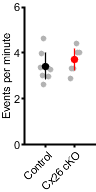

ylim([0 6]);


% Frequency without including area
con1Freq = (length(con1.ISCstruct.event)/maxTime); 
con2Freq = (length(con2.ISCstruct.event)/maxTime);
con3Freq = (length(con3.ISCstruct.event)/maxTime);
con4Freq = (length(con4.ISCstruct.event)/maxTime);
con5Freq = (length(con5.ISCstruct.event)/maxTime);
con6Freq = (length(con6.ISCstruct.event)/maxTime);
%con7Freq = (length(con7.ISCstruct.event)/maxTime); % very flat, large
con8Freq = (length(con8.ISCstruct.event)/maxTime);

cx261Freq = (length(cx261.ISCstruct.event)/maxTime);
cx262Freq = (length(cx262.ISCstruct.event)/maxTime);
cx263Freq = (length(cx263.ISCstruct.event)/maxTime);
cx264Freq = (length(cx264.ISCstruct.event)/maxTime);
cx265Freq = (length(cx265.ISCstruct.event)/maxTime);
%cx266Freq = (44/8.09)/(size(cx266.ISCstruct.rois,2)*areaPG)*10000; % small
cx267Freq = (length(cx267.ISCstruct.event)/maxTime);
cx268Freq = (length(cx268.ISCstruct.event)/maxTime);
cx269Freq = (length(cx269.ISCstruct.event)/maxTime);

conFreq = [con1Freq,con2Freq,con3Freq,con4Freq,con5Freq,con6Freq,con8Freq]

conFreq =     6.6231    7.1173    5.9311    7.7105    8.5013    8.3036    7.7105


cx26Freq = [cx261Freq,cx262Freq,cx263Freq,cx264Freq,cx265Freq,cx267Freq,cx268Freq,cx269Freq]

cx26Freq =     7.4139    8.9955    8.3036    8.5013    8.9955    9.0944    6.4254    6.8208


conditions = {'Control','Cx26 cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Events per minute');
[fig1 h p1] = compare2(conFreq,cx26Freq,conditions,ylbl,dim,markSz)

     0



fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 0

p1 = 0.2239

p1

p1 = 0.2239

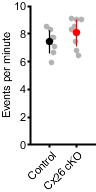

ylim([0 10]);


% mean event size
con1size = mean([con1.ISCstruct.event.area]);
con2size = mean([con2.ISCstruct.event.area]);
con3size = mean([con3.ISCstruct.event.area]); 
con4size = mean([con4.ISCstruct.event.area]);
con5size = mean([con5.ISCstruct.event.area]);
con6size = mean([con6.ISCstruct.event.area]);
con7size = mean([con7.ISCstruct.event.area]);
con8size = mean([con8.ISCstruct.event.area]);

cx261size = mean([cx261.ISCstruct.event.area]);
cx262size = mean([cx262.ISCstruct.event.area]);
cx263size = mean([cx263.ISCstruct.event.area]);
cx264size = mean([cx264.ISCstruct.event.area]);
cx265size = mean([cx265.ISCstruct.event.area]);
cx266size = mean([cx266.ISCstruct.event(1:44).area]);
cx267size = mean([cx267.ISCstruct.event.area]);
cx268size = mean([cx268.ISCstruct.event.area]);
cx269size = mean([cx269.ISCstruct.event.area]);

conSize = [con1size,con2size,con3size,con4size,con5size,con6size,con7size,con8size] * areaPG

conSize =   699.6371  761.1554  505.5221  567.3867  494.5673  603.1797  538.8905  671.6727


cx26Size = [cx261size,cx262size,cx263size,cx264size,cx265size,cx266size,cx267size,cx268size,cx269size] * areaPG

cx26Size =   456.8081  521.9351  553.9406  455.2905  506.0271  493.5107  475.0509  526.0258  574.4569



ylbl = ('Mean event size (um2)');
[fig2 h p2] = compare2(conSize,cx26Size,conditions,ylbl,dim,markSz)

     1



fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 396
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 1

p2 = 0.0140

p2

p2 = 0.0140

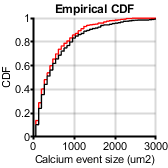

ylim([0 800])

allSizeCon = [con1.ISCstruct.event.area,con2.ISCstruct.event.area,con3.ISCstruct.event.area,con4.ISCstruct.event.area,con5.ISCstruct.event.area,con6.ISCstruct.event.area,con7.ISCstruct.event.area,con8.ISCstruct.event.area]* areaPG;
allSizeCx26 = [cx261.ISCstruct.event.area,cx262.ISCstruct.event.area,cx263.ISCstruct.event.area,cx264.ISCstruct.event.area,cx265.ISCstruct.event.area,cx266.ISCstruct.event.area,cx267.ISCstruct.event.area,cx268.ISCstruct.event.area,cx269.ISCstruct.event.area]* areaPG;


figure
h1 = cdfplot(allSizeCx26);
hold on
h2 = cdfplot(allSizeCon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Calcium event size (um2)');
ylabel('CDF');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 3000])

[h p] = kstest2(allSizeCon,allSizeCx26);
p

p = 0.3642


secPerFrame = 0.4855

secPerFrame = 0.4855

con1Dur = mean([con1.ISCstruct.event.eventDuration])*secPerFrame;
con2Dur = mean([con2.ISCstruct.event.eventDuration])*secPerFrame;
con3Dur = mean([con3.ISCstruct.event.eventDuration])*secPerFrame;
con4Dur = mean([con4.ISCstruct.event.eventDuration])*secPerFrame;
con5Dur = mean([con5.ISCstruct.event.eventDuration])*secPerFrame;
con6Dur = mean([con6.ISCstruct.event.eventDuration])*secPerFrame;
con7Dur = mean([con7.ISCstruct.event.eventDuration])*secPerFrame;
con8Dur = mean([con8.ISCstruct.event.eventDuration])*secPerFrame;

cx261Dur = mean([cx261.ISCstruct.event.eventDuration]*secPerFrame);
cx262Dur = mean([cx262.ISCstruct.event.eventDuration]*secPerFrame);
cx263Dur = mean([cx263.ISCstruct.event.eventDuration]*secPerFrame);
cx264Dur = mean([cx264.ISCstruct.event.eventDuration]*secPerFrame);
cx265Dur = mean([cx265.ISCstruct.event.eventDuration]*secPerFrame);
cx266Dur = mean([cx266.ISCstruct.event.eventDuration]*secPerFrame);
cx267Dur = mean([cx267.ISCstruct.event.eventDuration]*secPerFrame);
cx268Dur = mean([cx268.ISCstruct.event.eventDuration]*secPerFrame);
cx269Dur = mean([cx269.ISCstruct.event.eventDuration]*secPerFrame);

conDur = [con1Dur,con2Dur,con3Dur,con4Dur,con5Dur,con6Dur,con7Dur,con8Dur]

conDur =     6.6376    6.7093    6.7646    6.4049    5.6849    6.2190    5.9695    6.5667


cx26Dur = [cx261Dur,cx262Dur,cx263Dur,cx264Dur,cx265Dur,cx266Dur,cx267Dur,cx268Dur,cx269Dur]

cx26Dur =     5.4117    5.9861    6.4560    6.1083    6.0021    6.4329    5.9685    7.0958    6.7266



ylbl = ('Mean duration (s)');
[fig3 h p3] = compare2(conDur,cx26Dur,conditions,ylbl,dim,markSz)

     0



fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 398
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 0

p3 = 0.5683

p3

p3 = 0.5683

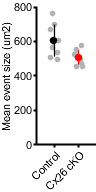

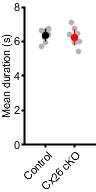

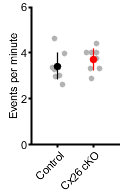

ylim([0 8])

subP = handleTheSubplot({fig1,fig3,fig2},[1 3]);

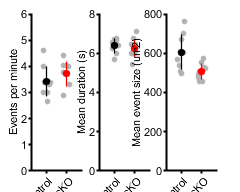

figQuality(subP,gca,[2.5 2])


[CorrP CorrA h] = fdr_BH([p1,p2,p3],0.05)

CorrP =     0.4620    0.0421    0.5683


CorrA =     0.0333    0.0167    0.0500


h = 3×1 logical array
   0
   1
   0


%


% show ROI raster from control and cKO 
n = length(con1.ISCstruct.corrROIs);
t = 1250;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con1.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

n = length(cx263.ISCstruct.corrROIs);
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(cx263.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])


[matx1 probRelCon1] = genReleaseMatx(con1);
[matx2 probRelCon2] = genReleaseMatx(con2);
[matx3 probRelCon3] = genReleaseMatx(con3);
[matx4 probRelCon4] = genReleaseMatx(con4);
[matx5 probRelCon5] = genReleaseMatx(con5);
[matx6 probRelCon6] = genReleaseMatx(con6);
[matx7 probRelCon7] = genReleaseMatx(con7);
[matx8 probRelCon8] = genReleaseMatx(con8);

conRelease = mean([probRelCon1,probRelCon2,probRelCon4,probRelCon5,probRelCon6,probRelCon7,probRelCon8],2)

conRelease =     0.5268
    0.1577
    0.0924
    0.0952
    0.0681
    0.0414
    0.0147
    0.0025
    0.0012
         0


conMean = cat(2,probRelCon1,probRelCon2,probRelCon4,probRelCon5,probRelCon6,probRelCon7,probRelCon8)

conMean =     0.5970    0.5833    0.5128    0.5233    0.6071    0.3130    0.5513
    0.1343    0.2083    0.2692    0.0814    0.0833    0.1478    0.1795
    0.1194    0.0972    0.0641    0.1163    0.0595    0.1130    0.0769
    0.0597    0.0694    0.0769    0.1163    0.1071    0.1217    0.1154
    0.0597    0.0278    0.0128    0.1047    0.1071    0.1130    0.0513
    0.0299    0.0139    0.0513    0.0465    0.0357    0.0870    0.0256
         0         0    0.0128    0.0116         0    0.0783         0
         0         0         0         0         0    0.0174         0
         0         0         0         0         0    0.0087         0
         0         0         0         0         0         0         0


conSTD = std(conMean,1,2)/sqrt(7)

conSTD =     0.0353
    0.0237
    0.0089
    0.0090
    0.0142
    0.0083
    0.0100
    0.0023
    0.0012
         0


figure
x = [0:1:11]*10*scale

x =          0    8.3027   16.6054   24.9081   33.2108   41.5135   49.8162   58.1189   66.4216   74.7243   83.0270   91.3297


shadedErrorBar(x,conRelease,conSTD)
hold on

[matx1 probRelCx1] = genReleaseMatx(cx261);
[matx2 probRelCx2] = genReleaseMatx(cx262);
[matx3 probRelCx3] = genReleaseMatx(cx263);
[matx4 probRelCx4] = genReleaseMatx(cx264);
[matx5 probRelCx5] = genReleaseMatx(cx265);
[matx7 probRelCx7] = genReleaseMatx(cx267);
[matx8 probRelCx8] = genReleaseMatx(cx268);

cxRelease = mean([probRelCx1,probRelCx2,probRelCx3,probRelCx4,probRelCx5,probRelCx7,probRelCx8],2)

cxRelease =     0.4784
    0.1605
    0.1288
    0.1041
    0.0720
    0.0409
    0.0138
    0.0016
         0
         0


cxMean = cat(2,probRelCx1,probRelCx2,probRelCx3,probRelCx4,probRelCx5,probRelCx7,probRelCx8)

cxMean =     0.5600    0.5385    0.5357    0.4767    0.4286    0.3478    0.4615
    0.2267    0.0659    0.1786    0.1163    0.1538    0.2283    0.1538
    0.0933    0.1209    0.0357    0.2093    0.1099    0.1630    0.1692
    0.0533    0.1319    0.1548    0.1047    0.0769    0.1304    0.0769
    0.0267    0.0989    0.0833    0.0581    0.1209    0.0543    0.0615
    0.0400    0.0330    0.0119    0.0349    0.0769    0.0435    0.0462
         0         0         0         0    0.0330    0.0326    0.0308
         0    0.0110         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


cxSTD = std(cxMean,1,2)/sqrt(7)

cxSTD =     0.0261
    0.0203
    0.0200
    0.0128
    0.0110
    0.0068
    0.0060
    0.0015
         0
         0


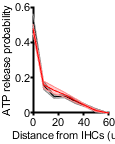

shadedErrorBar(x,cxRelease',cxSTD,'lineprops','r')
xlim([0 60])
xticks([0 20 40 60])
ylabel('ATP release probability');
xlabel('Distance from IHCs (um)')
figQuality(gcf,gca,[1.2 1.5])

%print(gcf,'-dpdf')

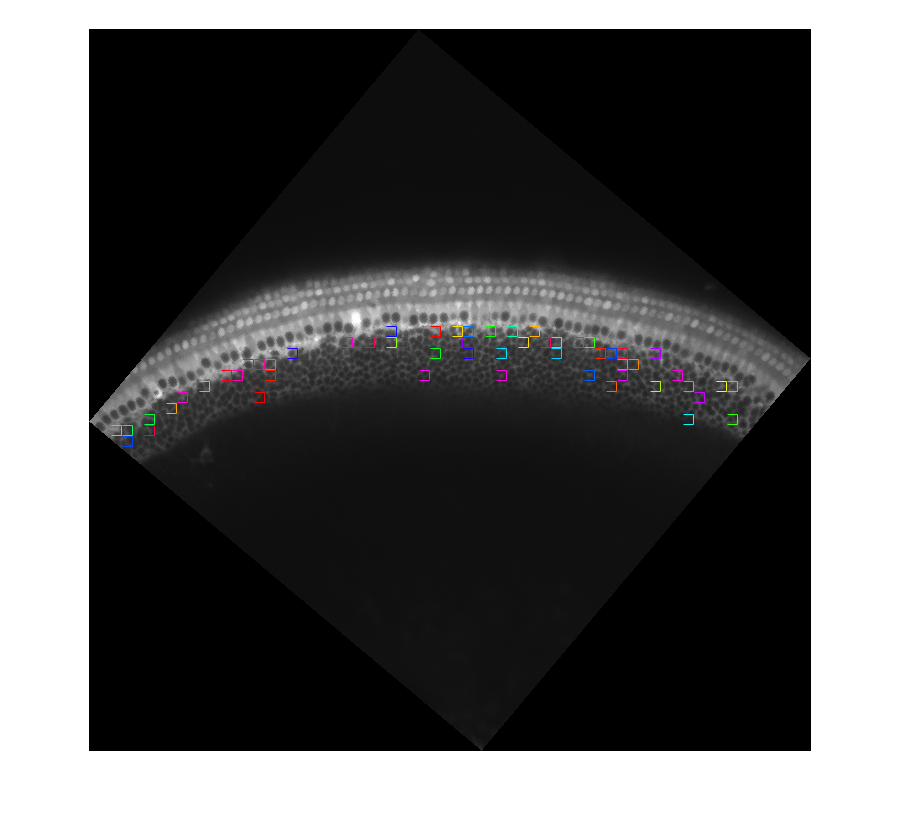


% Example release locations
% small calcium events fail to elicit significant ion flux and osmotic
% drive

[matx8 probRelCon8] = genReleaseMatxwithIMG(con2);

colorTicks([con2.ISCstruct.event(:).timeStart]', 1250)

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 22
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


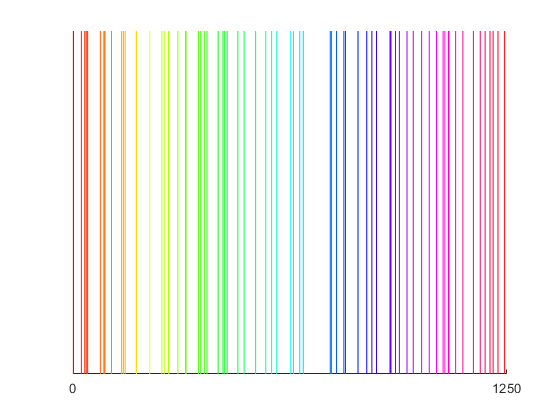

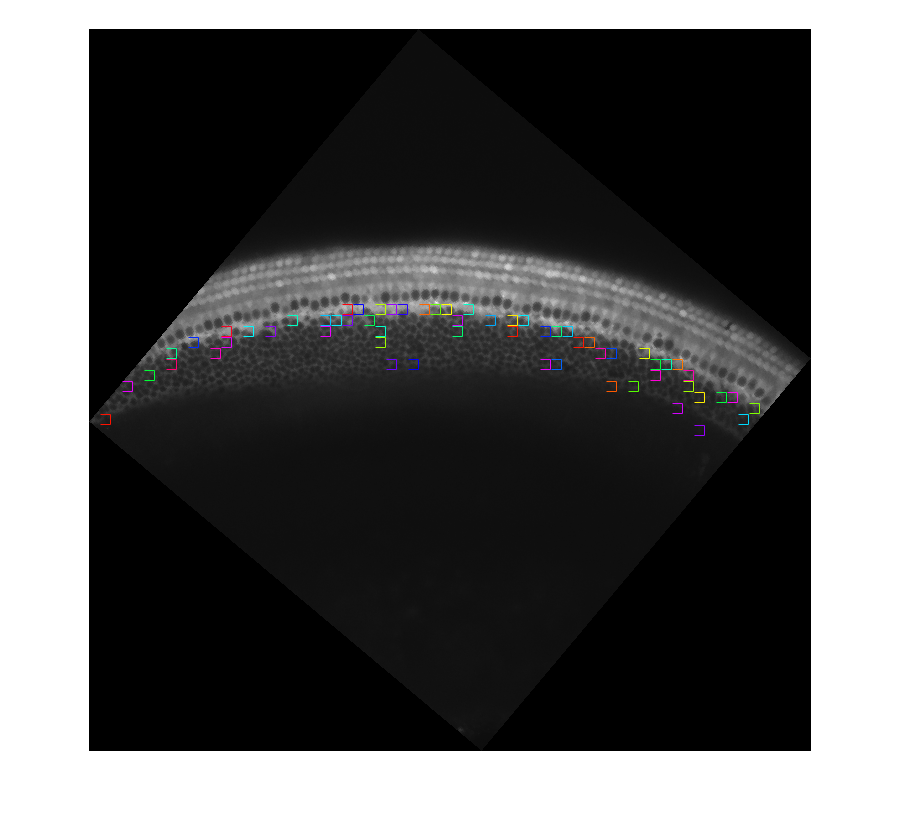


[matx1 probRelCx1] = genReleaseMatxwithIMG(cx261);

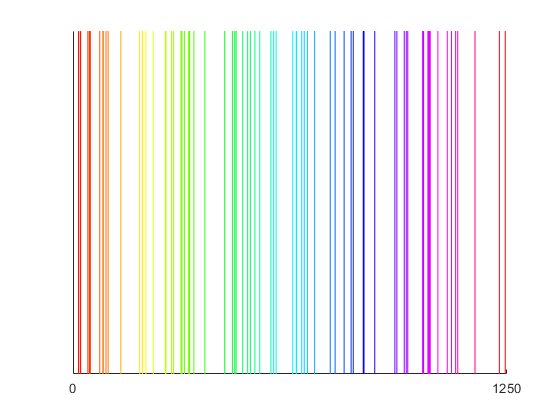

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


colorTicks([cx261.ISCstruct.event(:).timeStart]', 1250)